# MIA analysis Experiment

import and preprocess data:

load("data.mat");
d = int32(d);
s = int32(s);
wave = int32(wave);

s_box:

for k = 0:255
    for i = 1:1000
        v(i, k+1) = s(bitxor(d(i), k)+1);
    end
end

hamming_weight:

hw = zeros(1000, 256, 'int32');
%1000: D
%256: K
for i = 1:8
    hw = hw + mod(v, 2);
    v = idivide(v, 2);
end

probability distribution:

p = zeros(256, 2000, 9, 8);
phw = zeros(256, 9);
po = zeros(2000, 8);

for k = 0:255
    for t = 0:1999
        for n = 1:1000
            for o = 1:8
                if ((o-8)*5000 <= wave(n,t+1)) && ((o-7)*5000 > wave(n,t+1))
                    p(k+1,t+1,(hw(n,k+1)+1),o) = p(k+1,t+1,(hw(n,k+1)+1),o) + 1;
                end
            end
        end
    end
end
p = p/1000;

for k = 0:255
    for n = 1:1000
        phw(k+1,(hw(n,k+1)+1)) = phw(k+1, (hw(n,k+1)+1)) + 1;
    end
end
phw = phw/1000;

for t = 0:1999
    for n = 1:1000
        for o = 1:8
            if ((o-8)*5000 <= wave(n,t+1)) && ((o-7)*5000 > wave(n,t+1))
                po(t+1,o) = po(t+1,o) + 1;
            end
        end
    end
end
po = po/1000;

mutual information:

I = zeros(256, 2000);
for k = 0:255
    for t = 0:1999
        for lhw = 0:8
            for o = 1:8
                if p(k+1,t+1,lhw+1,o) ~= 0
                    temp = p(k+1,t+1,lhw+1,o) / (phw(k+1,lhw+1) * po(t+1,o));
                    I(k+1,t+1) = I(k+1,t+1) + p(k+1,t+1,lhw+1,o) * log(temp) / log(2);
                end
            end
        end
    end
end

Find maximum:

[M, IND] = max(I, [], "all");
[row, col] = ind2sub(size(I), IND);
ck = row-1;
ct = col-1;

Save the result:

save("output_MIA.mat");

Paint:

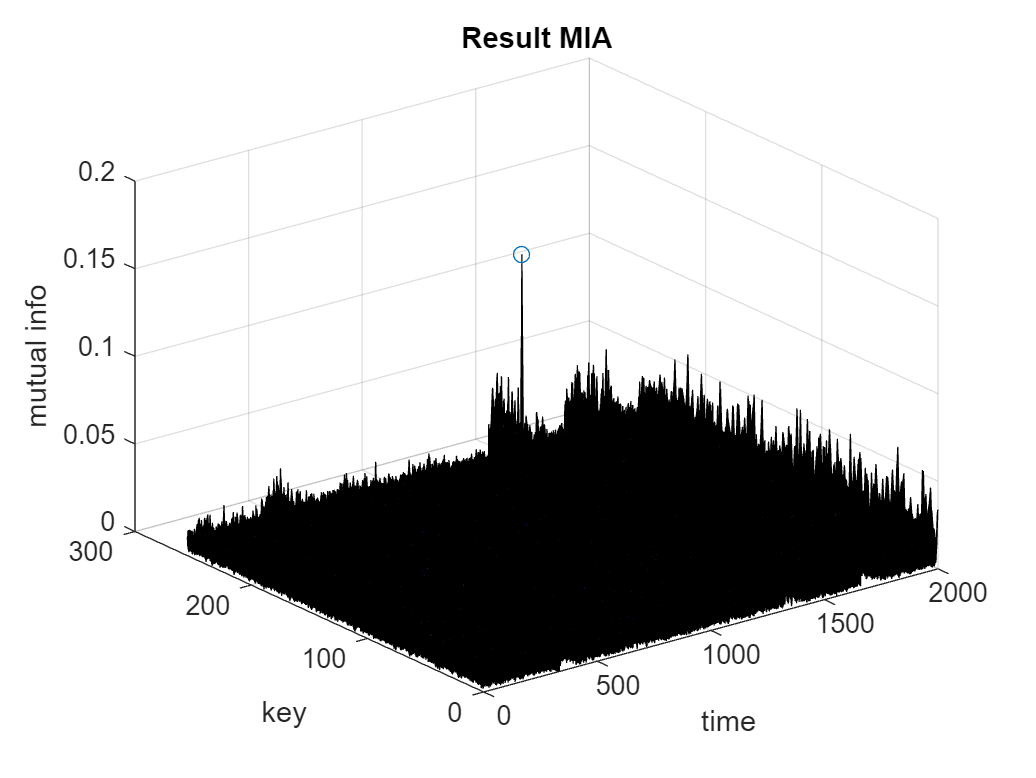

[X, Y] = meshgrid(0:1999, 0:255);
surf(X, Y, I);
hold on;
xlabel('time');
ylabel('key');
zlabel('mutual info');
title('Result MIA');
hold on;
scatter3(ct, ck, M);
hold off;